clear all

% Model Parameters (extracted from Table S1 in SI)
% ====================================================
%                  [Unit]   Variable definition
% ====================================================
n_m = 75;          %          Number of myosin motors
F_m = -2;          % [pN]     Single myosin motor stall force
v_u = -120;        % [nm/s]   Unloaded myosin motor velocity
n_c = 75;          %          Number of molecular clutches
k_on = 1;          % [s^(-1)] Rate of clutch binding
k_off = 0.1;       % [s^(-1)] Rate of clutch unbinding
F_b = -2;          % [pN]     Characteristic bond rupture force
k_clutch = 5;      % [pN/nm]  Molecular clutch spring constant
eta = 0.1;
k_substrate = 1;
F_stall = n_m * F_m;

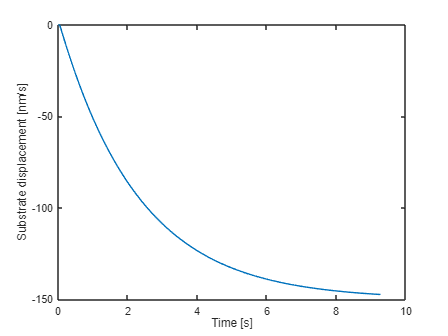

x_clutches = zeros(1, n_c);
clutch_states = zeros(1, n_c);
x_substrate = 0;
F_clutch = k_clutch * (x_clutches - x_substrate);
t = 0;
n_eng = 0;
v_substrate = 0;

n_events = 1e3;
x_substrate_events = zeros(1, n_events);
v_substrate_events = zeros(1, n_events);
event_type_events = zeros(1, n_events);
cell_velocity_events = zeros(1, n_events);
cell_velocity_events(1) = v_u;
t_events = zeros(1, n_events);

for i = 2:n_events
    % Find time of next event
    [is_bind, state_idx, dt] = simulate_next_event(clutch_states, F_clutch, k_on, F_b, k_off);
    
    % Displace cell and substrate according to time elapsed
    [clutch_displacement, x_substrate, v_substrate] = calc_displacement_numeric(eta, k_substrate, k_clutch, n_eng, v_u, F_stall, t, dt, x_substrate, v_substrate);
    
    % THIS FUNCTION TAKES LONG ASL ~ 1s a step
    % tic
    % [clutch_displacement, x_substrate, v_substrate] = calc_displacement(eta, k_substrate, k_clutch, n_eng, v_u, F_stall, t, dt, x_substrate, v_substrate);
    % toc
    
    engaged_clutch_idx = find(clutch_states==1);
    disengaged_clutch_idx = find(clutch_states==0);
    n_eng = length(engaged_clutch_idx);
    
    x_clutches(engaged_clutch_idx) = x_clutches(engaged_clutch_idx) + clutch_displacement;
    x_clutches(disengaged_clutch_idx) = x_substrate;
    
    % Change clutch states
    clutch_states(state_idx) = is_bind;
    if ~is_bind
        x_clutches(state_idx) = x_substrate;
    end
    
    % Calculate force on the clutches
    F_clutch = k_clutch * (x_clutches - x_substrate);

    t = t + dt;

    % Save variables for plotting
    x_substrate_events(i) = x_substrate;
    v_substrate_events(i) = v_substrate;
    event_type_events(i) = is_bind;
    cell_velocity_events(i) = clutch_displacement / dt;
    t_events(i) = t;
end

plot(t_events, x_substrate_events, '-');
ylabel("Substrate displacement [nm/s]");
xlabel("Time [s]");

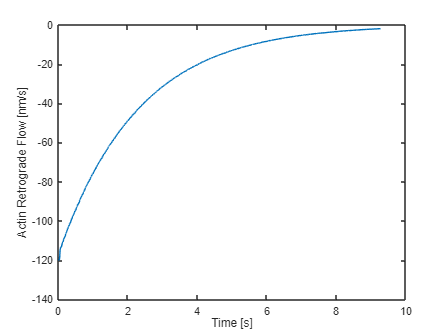


plot(t_events, cell_velocity_events, '-');
ylabel("Actin Retrograde Flow [nm/s]");
xlabel("Time [s]");